hypLR = linPredict(X,theta);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Error in linPredict (line 4)
y = [ones(size(X,1), 1) X]*theta;


hypLR_tst = hypLR(2400:end);

yr = [y_train; y_cv; y_test];
yr_tst = yr(2400:end);

size(hypLR_tst)
size(yr_tst)

y = yr_tst.*mx_y;
h = hypLR_tst.*mx_y;

MAE = mae(h-y)

MSE = mse(h-y)
mape = mean(abs((h-y)./y))*100
mxmape = max(abs((h-y)./y))*100
mnmape = min((abs((h-y)./y))*100)

plot(y);
hold on
plot(h)
legend('real','pred')
hold off

plot(y-h)

hist(h-y)

load('hyp_FNN2.mat')
size(hyp_FNN2)

ans =         3009           1


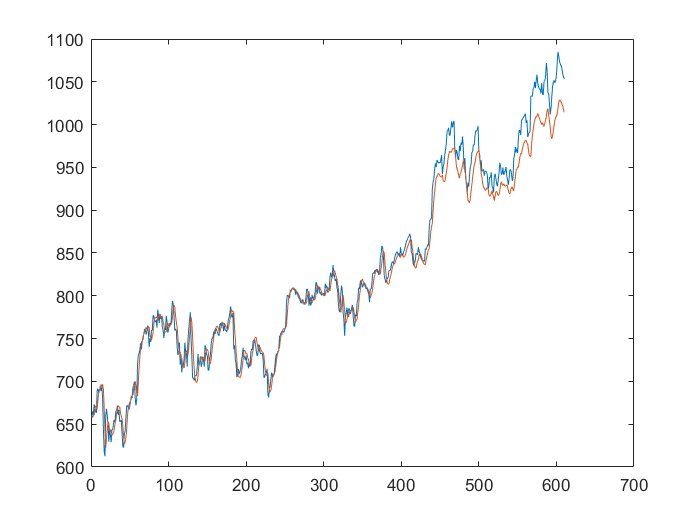


h = hyp_FNN(2400:end).*mx_y;
y = yr(2410:end);


plot(y)
hold on
plot(h)
hold off

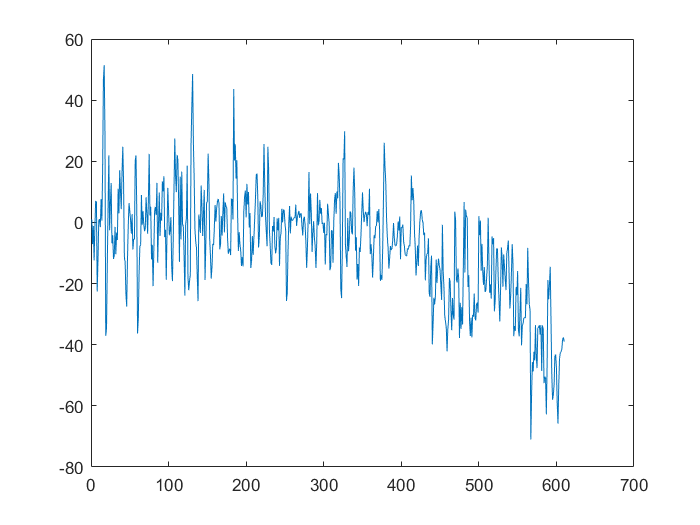


loss = h-y;
plot(loss)



MAE = mae(h-y)

MAE = 14.0619


MSE = mse(h-y)

MSE = 369.8667

mape = mean(abs((h-y)./y))*100

mape = 1.6246

mxmape = max(abs((h-y)./y))*100

mxmape = 8.3259

mnmape = min((abs((h-y)./y))*100)

mnmape = 1.9472e-05